# E9

# Reconeixement

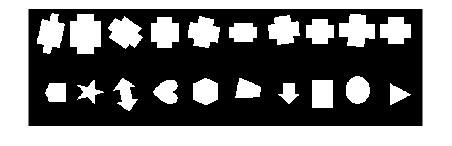

BW = rgb2gray(imread('creus_no_creus.png')) < 200;
imshow(BW);


% Classificar les figures com creus o no creus
BWU = BW(1:end/2,:); 
BWD = BW(end/2:end,:);

CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table',CCU,'Centroid','BoundingBox','Circularity','Solidity','Extent','MinFeretProperties','MaxFeretProperties','Perimeter','MinorAxisLength','MajorAxisLength');
propsD = regionprops('table',CCD,'Centroid','BoundingBox','Circularity','Solidity','Extent','MinFeretProperties','MaxFeretProperties','Perimeter','MinorAxisLength','MajorAxisLength');

NumObj = CCU.NumObjects; % nombre d'objectes trobats a la fila de dalt

% Construim el vector de caracteristiques
FU = [propsU.Perimeter./propsU.MinFeretDiameter, propsU.Circularity, propsU.Solidity, propsU.Extent, propsU.MinorAxisLength./propsU.MajorAxisLength,propsU.MinFeretDiameter./propsU.MaxFeretDiameter];
FD = [propsD.Perimeter./propsD.MinFeretDiameter, propsD.Circularity, propsD.Solidity, propsD.Extent, propsD.MinorAxisLength./propsD.MajorAxisLength,propsD.MinFeretDiameter./propsD.MaxFeretDiameter];

% Construim la taula per classificar
Features = [FU;FD];
Output = false([2*NumObj,1]);
Output(1:NumObj) = true;
